## Data description

HIV Associated Neurocognitive Disorder (HAND) is a recent development in the aging HIV population. Due to both toxicities in the therapies used to treat the disease or from HIV itself, patients are beginning to have deficits in their psychomotor functions as well as short-term memory loss. This is further exacerbated by the use of illicit drugs; a common co-variate with HIV infection. The Total Modified Hopkins Dementia Score (TMHDS) is a tool that is used to assess this in large patient populations. The score ranges from 0 to 12 with a score of 10 or above being considered "normal".

The hopkinsdata.xlsx file contains the data from a study of a cocaine abusing HIV-1 cohort. Patients were asked to return approximately 6 months apart for 6 visits and during their study visit they were subjected to the TMHD test and blood was drawn for subsequent drug testing.

The Excel file has three worksheets, containing the age, drug, and score data. Each row represents a patient and each column represents a visit.

## Variable names

- The *age* variable contains the age at the time of visit for each patient (rows are patients and columns are visits).

- The *drug* variable contains the information on whether the patient tested positive for cocaine (True) or did not (False) at each visit.

- The *score* variable contains the TMHDS for each patient at each visit.

## Objectives:

- Understand the data.  Two main independent variables (age & drug use) and one possibly dependent one (TMHDS).  TMHDS may depend on either one or both. 

- Read the individual sheet of an excel file into a cell array with xlsread() 

- ttest(), polyfit(), Statistics of the line fit fitlm()

- box plot,  scatter plot

- captions and conclusions

## Load the data

Read the age, drug, and score worksheets in the Excel file into age, drug, score variables.

age=xlsread('hopkinsdata.xlsx','age');
drug=xlsread('hopkinsdata.xlsx','drug');
score=xlsread('hopkinsdata.xlsx','score');

# Variation in time between visits

Patients don't visit exactly at six months. Use the data in the *age* to determine how often patients actually come in.

% Use diff to calculate the number of years between each subsequent visit
% by a patient. Hint: the results should be a 500x5 matrix
% agediff = diff(age,1,2)*12

% 6.28407422	8.361121474	15.73837849	14.02121617	9.659452858
% 28.59080755	14.44109284	11.47763106	28.10189407	3.11065501
% 7.456956882	1.646976664	1.159612525	5.940932045	17.00984942
% 4.239551735	1.409271126	3.233696856	4.979577982	19.22301405

agediff = diff(?)*12;
% flatten agediff convert from 2D to 1D
avgagediff=mean(agediff(:))
stdagediff=std(?)

% Generate a histogram using a "flattened" version of this matrix. Use some
% annotations to mark the average and standard deviation.
% hist( agediff,0:1:50 ), xlabel('?'); ylabel('?');
% plot lines of avgagediff, avgagediff-stdagediff ,avgagediff+stdagediff 

clf,hold on
hist(agediff(?),?)
hold off

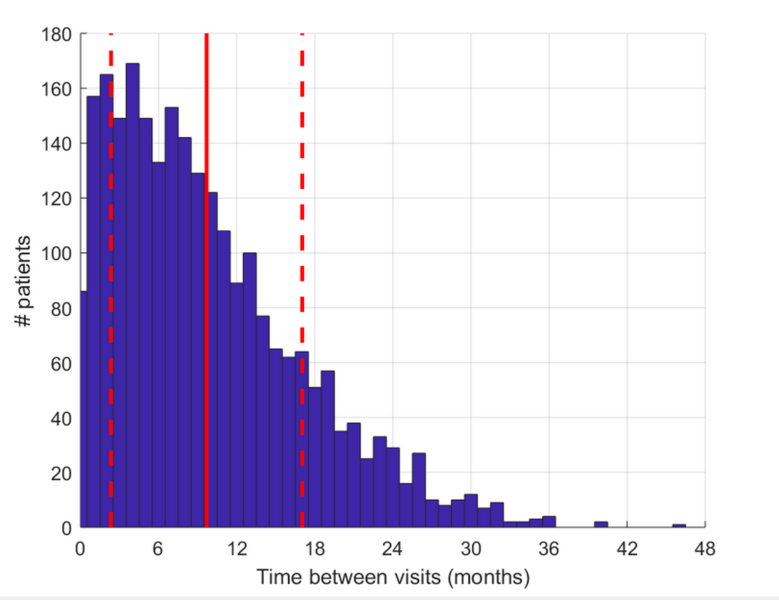

**Captions.**

**Conclusions.**

# Does drug use affect how often a patient comes into the clinic?

% calculate the mean use of drug for each patient
% avguse 500x1 matrix
% calculate the mean visit of each patient
% avguse 500x1 matrix
% avgvisit 500x1 matrix
avguse = mean(?)
avgvisit = mean (?)

% Use a boxplot to answer: Does drug use affect a patient's return
% frequency?
boxplot(?)
%round the x axis ticks using %.2f..

xlabel('Average drug use of patient');
ylabel('Time b/w visits (months)');

%round the x axis ticks using %.2f..

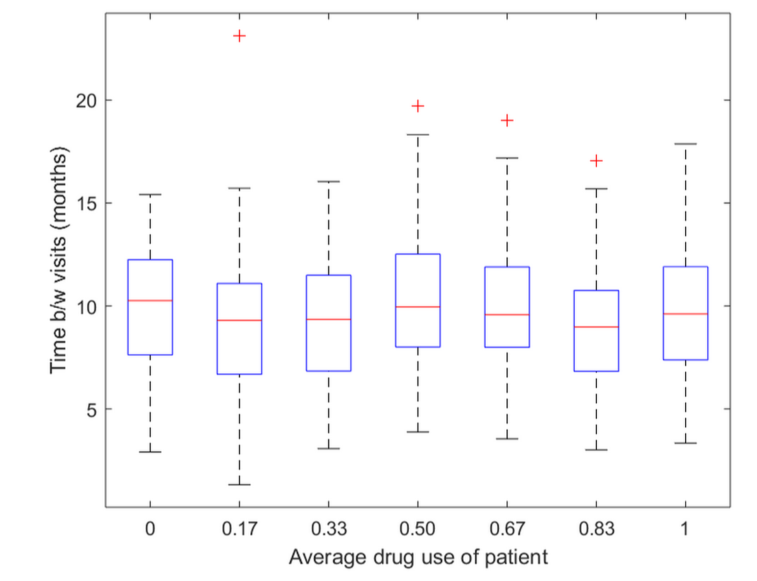

Captions.

Conclusions.

# Effect of age on TMHDS

First, we'll look at whether age is correlated with TMHDS score.

% Use a scatter-plot to answer: Does the patient's age correlate with theTMHDS
% mean (age, dim) of each patient
% mean (score, dim) of each patient
% scatter plot age and score
% linear regression between age and score with polyfit
% print slope and intercept
% answer the question "whether age is correlated (negatively or positively)with 
% TMHDS score" by calculating the correlation coefficient, and why? 
% corrcoef(). https://www.mathworks.com/help/matlab/ref/corrcoef.html
% plot the trend line

figure
a=mean (age, dim)
b= mean (score, dim)
scatter(mean (age, dim),mean (score, dim))
trend=polyfit(a,b,1)
slope =?
intercept=?

xlabel('Average age of patient');
ylabel('average score');
hold on
plot( the a trend line)

corrcoef (mean(age,?), mean(score,?))

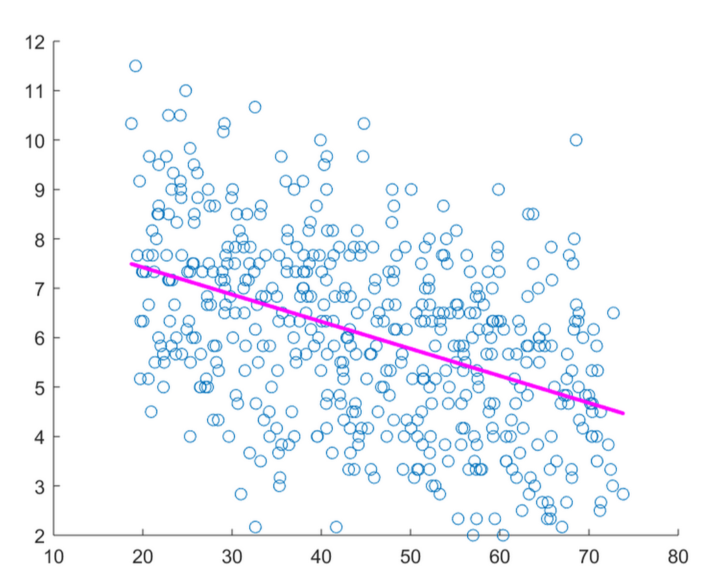

Captions.

Conclusions.

# Effect of age on the rate of change of TMHDS scores

Next, we want to ask whether TMHDS of old patients  decrease faster

% Calculate the rate of change of TMHDS for each patient vs age. use the slope of the polyfit.
rates = zeros(size(score,1), 1);
for i=1:size(score,1)
    trend=polyfit(age(?,?)),score(?,?))
    rates(i)=trend(?)
    
end

% Does this correlate with age? plot the scatter plot and the trendline
% figure 
% scatter plot of age vs. the rates 
% trendandplot(mean(age,2), rates, 'scatter')

% use the corrcoef() to answer the question:  Does this correlate with age?  why? p 0,05, 0.01
[R,P]=corrcoef(mean(age,dim),rates)

# Which is more important?

What we often want to know when there are two independent variables is: Which is more important: age or drug use? There are many ways to do this but the simplest is to group the patients. Within this set of "drug-using" patients, there are some that never tested positive for drug use. These patients can be used to determine the effect of age alone. This can then be compared to age-matched patients who tested positive for varying levels of drug use.

% Develop a figure that answers the question: Which has a larger effect,
% aging or drug use?

% construct seven drug groups (0,1,2,3,4,5,6) based on the sum of all drug use for each patient. plot linear regression of the mean age vs. mean scores
% add the trend line
% calculate the correlation coefficient for each group 
% answer the question "which drug group has the highest correlation coefficient between age and score" and why?. 

for i=0:6
	I= sum(drug,2)==i;
 subplot(1,7,?)
 scatter(mean (age(?,?) dim),mean (score(?,?), dim))
	trend=polyfit((age(?,?) dim),mean (score(?,?), dim))
    trend(1), trend(2)
    plot()
end

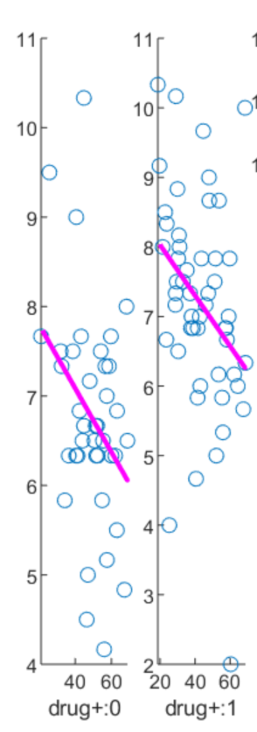

Captions.

Conclusions.

# Bonus questions: (5 points)

% in 5 groups of mean age between 18-30, 30-40, 40-50,50-60 and 60-74 
% plot linear regression of the mean drug use vs. mean scores
% calculate correlation coefficient for each group
% answer the question "which age group has the highest correlation between drug use and score" 
% and why?. 